% Clear the Command Window and workspace
clc
clear all

% Set simulation time step
Tsim = 0.1;

% Define thermal resistance values (in units, Kelvin/Watt)
R_s2w = 0.012;
R_c2s = 0.009;
R_w2r = 0.035;
R_s2r = 0.025;
R_r2a = 0.120;

% Define thermal capacitance values (in Joules/Kelvin)
C_s = 5.0e3;
C_w = 2.5e3;
C_r = 8.0e3;

% Calculate thermal conductance (inverse of resistance)
G_s2w = 1/R_s2w;
G_c2s = 1/R_c2s;
G_w2r = 1/R_w2r;
G_s2r = 1/R_s2r;
G_r2a = 1/R_r2a;

% Construct the conductance matrix G
G = [G_s2w + G_w2r, -G_s2w               ,   -G_w2r               ;
     -G_s2w       , G_s2w + G_c2s + G_s2r,   -G_s2r               ;
     -G_w2r       , -G_s2r               ,   G_r2a + G_s2r + G_w2r;];

% Construct the external conductance matrix Gex 
Gex = [0 G_c2s 0    ;
       0 0     G_r2a;]';

% Construct the capacitance matrix C   
C = diag([C_w,C_s,C_r]);

% Generate random seeds for simulations
Seed = round(rand(1,5) * 100);

% Set total simulation time
T_total = 8000;

% Set sampling times of losses and ex temperature boundaries
Ts_p = 150;
Ts_c= 250;
Ts_am= 250;
% Run the simulation with the model named "Simulation.slx"
simdata = sim("Simulation.slx");

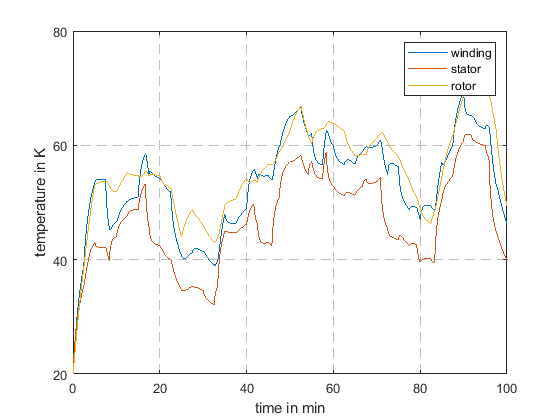

T = {};
M = {};
T.time = simdata.T{1}.Values.Time/60;
T.T_w = simdata.T{1}.Values.Data(:,1);
T.T_s = simdata.T{1}.Values.Data(:,2);
T.T_r = simdata.T{1}.Values.Data(:,3);
% Msub = simdata.M{1}.Values;
figure()
plot(T.time,T.T_w)
hold on
plot(T.time,T.T_s)
plot(T.time,T.T_r)
hold off
xlim([0 100])
xticks(0:20:100)
ylim([20 80])
yticks(20:20:80)
xlabel("time in min")
ylabel("temperature in K")
legend("winding","stator","rotor")
grid on
ax = gca;
ax.GridLineStyle = '--';
ax.GridColor = [0.5 0.5 0.5];
ax.GridAlpha = 0.5;

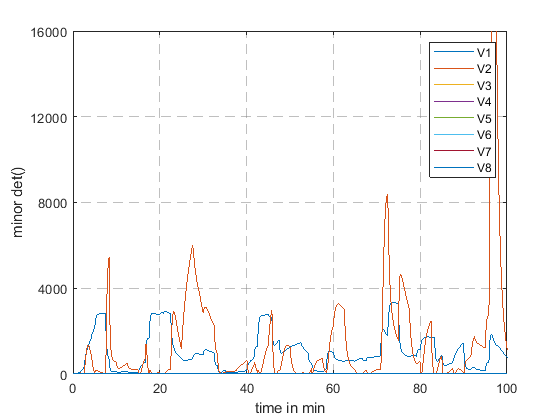


figure()
M.time = simdata.M{1}.Values.Time/60;
figure()
plot(M.time,simdata.M{1}.Values.Data(:,1));
hold on
for i = 2:8
    plot(M.time,simdata.M{1}.Values.Data(:,i));
end
hold off
xlim([0 100])
xticks(0:20:100)
ylim([0 16000])
yticks(0:4000:16000)
xlabel("time in min")
ylabel("minor det()")
legend("V1","V2","V3","V4","V5","V6","V7","V8")
grid on
ax = gca;
ax.GridLineStyle = '--';
ax.GridColor = [0.5 0.5 0.5];
ax.GridAlpha = 0.5;